puzzleImage = imread("Puzzle_01.jpg");
[MaskPuzzle,props] = processPuzzle(puzzleImage)

MaskPuzzle = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

props = 7×1 table
    Area 
    _____

    25654
     9841
    12390
    17529
    21455
     8559
     9269


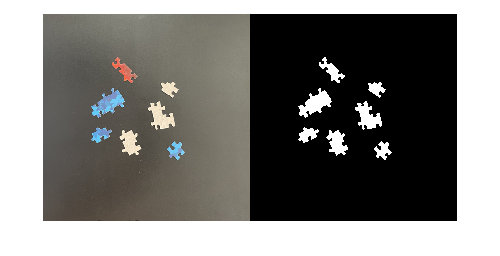

montage({puzzleImage,MaskPuzzle})

Let's calculate the percentage of true pixels in the mask produced by this function

truePixels = sum(MaskPuzzle(MaskPuzzle == 1))

truePixels = 104697

fractionTruePixels = truePixels / numel(MaskPuzzle) *100

fractionTruePixels = 4.5796

sum(props.Area)

ans = 104697

size(props,1)

ans = 7

Now let's apply batchproccesing of all the images using the datastore function

imagesFolder = 'C:\Users\21692\Desktop\coursera\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images\MathWorks Puzzle'

imagesFolder = 'C:\Users\21692\Desktop\coursera\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images\MathWorks Puzzle'

ds = datastore(imagesFolder,'Type','image')

ds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Images\MathWorks Puzzle\Puzzle_01.jpg';
                              ' ...\Data\MathWorks Images\MathWorks Puzzle\Puzzle_02.jpg';
                              ' ...\Data\MathWorks Images\MathWorks Puzzle\Puzzle_03.jpg'
                               ... and 47 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Images\MathWorks Puzzle'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


num_regions = [];
area_table = [];
while hasdata(ds)
    [PuzzleImage_i,info_image] = read(ds);
    [MaskPuzzle_i,props_i] = processPuzzle(PuzzleImage_i);
    num_regions = [num_regions ; size(props_i,1)];
    area_table = [area_table ; sum(props_i.Area)];
end

Property_Table = table(num_regions,area_table)

Property_Table = 50×2 table
    num_regions    area_table
    ___________    __________

         7          1.047e+05
        12         2.9244e+05
         8          1.548e+05
         8         1.6331e+05
         9         1.8994e+05
         5              56261
         9         1.3557e+05
         9         2.4598e+05
        16         1.9807e+05
         9              99351
        11         2.8712e+05
        11         1.9959e+05
         9          2.257e+05
        15         2.9436e+05
        10         1.4059e+05
        12         1.3066e+05


Let's analyze our table further

tot_num_regions = sum(Property_Table.num_regions)

tot_num_regions = 628

avg_area = sum(Property_Table.area_table)/tot_num_regions

avg_area = 1.5754e+04